# 숙제#12: 자세결정 및 제어부 실습 

**[2026-봄] 인공위성 시스템(ASE4080), 인하대학교 항공우주공학과**

**김창오 박사과정(cokim@inha.edu)**

#### 1. 자세제어 Part1: 자기토커 기반 제어

시뮬레이션 조건은 다음과 같다.

위성체

- 초기 궤도 $r^{\mathrm{ECI}} \left(t_0 \right)={\left\lbrack \begin{array}{ccc}
0 & -6878\ldotp 137 & 0
\end{array}\right\rbrack }^T \;\left\lbrack \mathrm{km}\right\rbrack$     $v^{\mathrm{ECI}} \left(t_0 \right)={\left\lbrack \begin{array}{ccc}
0 & 0 & 7\ldotp 612608
\end{array}\right\rbrack }^T \;\left\lbrack \mathrm{km}/s\right\rbrack$

- 초기 자세 $C_{\mathrm{ORF}}^{\mathrm{BRF}} =I_3$ (즉 BRF = ORF , Roll=Pitch=Yaw=0 deg)

- 초기 각속도 $\omega_{b/i}^b =\left\lbrack \begin{array}{ccc}
3 & 3 & 3
\end{array}\right\rbrack \;\deg /s$

- 관성 모멘트 $J=\mathrm{diag}\left(\left\lbrack \begin{array}{ccc}
0\ldotp 032 & 0\ldotp 007 & 0\ldotp 032
\end{array}\right\rbrack \right)\;\;\left\lbrack \mathrm{kg}\;\;m^2 \right\rbrack$

센서 및 구동기

- 자기 센서, 자이로 탑재. 측정 오차 없음  (지자기 벡터와 위성의 각속도 측정 가능)

- 자기토커는 총 3개가 탑재되었으며, 동체 좌표계(BRF)의 x,y,z 축과 정렬되어 있다고 가정한다.

시뮬레이션

- 종료 시간: 3 궤도

우주 환경 및 시간

- 궤도 외란: 없음 (이체모델 적용. 원하면 블록에서 드롭다운으로 추가 가능)

- 자세 외란: 없음 (원하면 중력 구배 토크 추가 가능)

- 시간: (UTC) 2026년 5월 19일 12시 0분 0초 

지자기장 모델은 다음과 같이 단순한 다이폴 모델이 적용되어 있다. NED 좌표계에서 표현하면 다음과 같다. 다음을 참고한다.

[https://en.wikipedia.org/wiki/Dipole_model_of_Earth%27s_magnetic_field](https://en.wikipedia.org/wiki/Dipole_model_of_Earth%27s_magnetic_field) 

$b^{\mathrm{NED}} =\left\lbrack \begin{array}{c}
b_N \\
b_E \\
b_D 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
B_0 {\left(R_E /r\right)}^3 \cos \delta \\
0\\
{2B}_0 {\left(R_E /r\right)}^3 \sin \delta 
\end{array}\right\rbrack$,  $\left\|\bm{b}\right\|=B_0 {\left(\frac{R_E }{r}\right)}^3 \sqrt{1+3\cos^2 \delta }$

참고로 $B_0 =3\ldotp 12\times {10}^{-5} \left\lbrack T\right\rbrack ,R_E =6378\ldotp 137\;\left\lbrack \mathrm{km}\right\rbrack$이다. $r,\delta ,\alpha$는 각각 거리, 적위(declination), 적경(right ascension)으로 ECI 좌표 성분 ${\bm{r}}^{\mathrm{ECI}} ={\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack }^I$로부터 아래와 같이 구할 수 있다. 


$$r=\sqrt{x^2 +y^2 +z^2 },\delta =\sin^{-1} \left(z/r\right)\;\;,\alpha =\mathrm{atan2}\left(y,x\right)\;,C_{\mathrm{ECI}}^{\mathrm{NED}} =\left\lbrack \begin{array}{ccc}
\sin \delta  & 0 & -\cos \delta \\
0 & 1 & 0\\
\cos \delta  & 0 & \sin \delta 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
-1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
\cos \alpha  & \sin \alpha  & 0\\
-\sin \alpha  & \cos \alpha  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


### vv 아래는 수정하지 않도록 한다 vv

clc; clear; close all
% vvvvvvvvvvvvvvvvvvv  Parameter (Do not Modify)  vvvvvvvvvvvvvvvvvvvv
R_E             =   6378.137;              % [km]
mu_E            =   398600.4418;           % [km^3/s^2]
R2D             =   180/pi;
D2R             =   pi/180;
W_E             =   7292115.0 * 10^-11;    % [rad/s] 
m2km            =   1e-3;
km2m            =   1e3;

addpath('library\');

% ============= Satellite =============
r0_eci          = [0 -6878.137 0]';  % position of satellite [km]
v0_eci          = [0 0 7.612608]';   % velocity of satellite [km/s]

% OE
a               = vis_viva(r0_eci,v0_eci,[],1); % Semi-major axis of orbit [km]
[e,ee]          = eccentricity(r0_eci,v0_eci);  % Eccentricity vector of orbit []

% Attitude : Find q0 (initial attitude quaternion)
z_orf           = -r0_eci/norm(r0_eci);
y_orf           = -cross(r0_eci,v0_eci)/norm(cross(r0_eci,v0_eci));
x_orf           = cross(y_orf,z_orf);
DCM0_eci2orf    = [x_orf' ; y_orf' ; z_orf'];
DCM0_orf2brf    = eye(3);

DCM0_eci2brf    = DCM0_orf2brf * DCM0_eci2orf;
q0_eci2brf      = DCM2Quaternion(DCM0_eci2brf);

% Rotation velocity
w_b_i2b         = [3 3 3];  % rotation velocity of the satellite [deg/s]

% MOI
J               = diag([0.032 0.007 0.032]);     % [kg m^2]

% ============= Simulation time =============
period          = 2*pi*sqrt(a^3/mu_E);
sim_time        = 3*round(period);
SIM_dt          = 1;

startdate       = juliandate(2026, 5, 19, 12, 0, 0);

% ^^^^^^^^^^^^^^^^^^^^^^^^  Parameter (Do not modify)  ^^^^^^^^^^^^^^^^^^^^^^^^

**1.1**) 'B-dot control' 기법은 자기토커를 이용하여 위성의 각속도를 감쇠하거나, 리액션휠의 누적된 모멘텀을 감소시키는 기법이다. 자세하게는 자기토커의 다이폴 모멘트와 지구 자기장이 상호작용하면서 토크가 생성되는 방식인데, 다이폴 모멘트의 크기에 따라 제어 토크가 결정된다. 따라서 회전하고 있는 위성을 목표 각속도까지 감쇠시키기 위해서는 적절한 다이폴 모멘트 크기를 갖는 자기토커 선정이 필요하다.

[https://satsearch.co/products/categories/satellite/attitude/actuators/magnetorquer](https://satsearch.co/products/categories/satellite/attitude/actuators/magnetorquer) 

**Q) **위와 같은 위성 제품 판매 사이트에서 3U 규격에 장착할 수 있는 자기토커를 선정하고** (1) 선택한 이유를 설명하시오. **그리고 데이터시트에 제공된 다이폴 모멘트 크기를 아래 셀의 파라미터로 입력하시오. 이후 시뮬링크 모델을 실행하고 PLOT 버튼을 눌러** (2) 3궤도 이내에 위성이 몇 deg/s까지 감쇠했는지, (3) 그때 다이폴 모멘트 명령은 어떻게 나왔는지 결과 그래프와 함께 설명하시오.**

% Margnetorquer dipole moment
% 변수명은 수정하지마시오.
Max_dipole = 0.5;               % [Am^2] 

**1.2 **B-dot 제어기의 제어 이득 K를 설계하시오. 

B-dot 제어의 성능은 자기토커 뿐만 아니라 제어 이득 (K)의 영향을 크게 받는다. 합리적인 제어 이득을 설계하기 위해 다양한 방법들이 연구되어 왔는데, 그 중 하나는 다음과 같다.

@ Avanzini, G., & Giulietti, F. (2012). Magnetic detumbling of a rigid spacecraft. *Journal of guidance, control, and dynamics*, *35*(4), 1326-1334.

============= 본 논문의 핵심 아이디어는 다음과 같다. 이 부분은 참고만 하도록 한다. ================== 

1) 자기토커는 지구 자기장에 수직한 방향의 제어토크만 만들 수 있다.

- 자기토커에 의한 토크는 $\tau =m\times b$ 이므로 항상 지구 자기장 $b$에 수직이다.

- 따라서 위성 각속도($\omega$)가 지구 자기장 벡터($b$)와 거의 평행해지면($\omega \;//\;b$), 자기토커로 유도되는 토크로는 위성 각속도를 줄이기 힘들어진다.

- 논문은 이러한 상황, 즉 $\omega \;//\;b$인 상황을 피하기 위해, 자기장에 수직한 동체 각속도 성분 $\omega_{\bot }$의 동역학을 분석하고, 적절한 제어 이득 $k_w$ 설계 방법을 제시한다.

2) 지구 자기장에 수직한 각속도 성분은 다음과 같다. $\omega_{\bot } =\left(I_3 -\hat{\bm{b}} {\hat{\bm{b}} }^T \right)\omega$.

3) 논문에서는 $\omega_{\bot }$의 시간에 따른 변화량을 -(자기토커 제어에 의한 Term)+(궤도 변화에 의해 생성되는 Term)으로 근사할 수 있음을 제시하고, 이 두 Term의 크기가 비슷해지도록 유도하는 제어 이득 $k_w$ 설계 방식을 제시한다. 더 자세한 수식은 논문을 참고하며, 결론적으로 논문에서 유도된 제어 이득은 아래와 같다.

=================================================================================


$$k_w =2n\left(1+\sin \xi_m \right)J_{\min }$$



$$K_{\mathrm{bdot}} =\frac{k_w }{{\left\|\bm{b}\right\|}^2 }$$


where, $n:$ 궤도의 평균 운동 (mean motion, [rad/s]) , $J_{\min }$: 관성 모멘트 성분 중 가장 작은 값 $\left\lbrack \mathrm{kg}\;m^2 \right\rbrack$ , $\xi_m$: 궤도 경사각과 지구 자기장 적도면이 이루는 각 = 궤도 각운동량 벡터와 지구 자기쌍극자 벡터가 이루는 각, $\left\|\bm{b}\right\|$: 지구 자기장 벡터의 크기

여기서 $\xi_m$은 시간에 따라 변하는 값이므로 B-dot 알고리즘의 게인 또한 시간에 따라 변해야 하는데, 실제 ADCS 소프트웨어에서 매 순간마다 이를 계산할 경우 구현 복잡도가 증가한다. 따라서 sine 함수의 성질을 이용하여 보수적으로 다음과 같이 Gain을 설계할 수 있다.

$k_w =2n\left(1+\sin \xi_m \right)J_{\min } \le 4{\mathit{nJ}}_{\min }$  ,   $K_{\mathrm{bdot}} =\frac{k_w }{{\left\|\bm{b}\right\|}^2 }$

**Q)** 1.1에서는 아래 임의의 값을 제어 이득으로 사용하였다. 이제 바로 위에 있는 보수적인 $k_w$ 유도 식을 문제 1의 파라미터들을 활용하여 아래 코드에서 구현하고 **1.1**의 결과와 비교하시오. "K_bdot" 변수명은 그대로 사용하고, 자기장 벡터 크기는 문제 설명에 주어진 값을 활용하시오. **위성 각속도 변화, 다이폴 모멘트 누적 출력**을 비교하고, 본인이라면 게인 값을 어떻게 설정할지 간단하게 의견을 제시하시오.

K_bdot  = 5000;

% ==================== DIY ====================

% ==================== DIY ====================

#### 2. 자세제어 Part 2: 리액션 휠 성능 결정 

1축 제어 문제를 가정한다. 다음 두 가지 제약 조건을 각각 만족하기 위한 리액션 휠의 성능(각운동량 $h_{\mathrm{RW},\max }$ 과 토크 $\tau_{\mathrm{RW},\max }$)을 결정하시오.

자세 파라미터는 다음과 같다.

$\theta$: 위성 자세 [deg], $\omega$: 위성 각속도  [deg/s], $a$: 위성 각가속도  [deg/s^2], $I_s =0\ldotp 10\;\;\left\lbrack {\mathrm{kgm}}^2 \right\rbrack$: 위성 관성 모멘트(1축 기동 가정)

제약 조건은 다음과 같다.

- 위성은 15초만에 10도에 도달할 수 있어야 한다. $\theta \left(t=15\right)={10}^{\circ } \;\;\&\;T=15$

- 위성은 25초만에 20도에 도달할 수 있어야 한다. $\theta \left(t=25\right)={20}^{\circ } \;\;\&\;T=25$

Rest-to-Rest(초기 및 최종 시간 각속도가 0인 문제) 기동 조건에서 Bang-Bang 제어기를 사용한다고 가정한다. 

$\omega \left(t=0\right)=\omega \left(t=25\right)=0^{\circ } \;\gets$ Rest-to-rest

$a=\left\lbrace \begin{array}{ll}
a_{\max }  & 0\le t<T/2\\
{-a}_{\max }  & T/2\le t<T
\end{array}\right.\;\;\;\gets$ Bang-Bang

위 조건에 의한 위성 자세 프로파일은 다음과 같다.

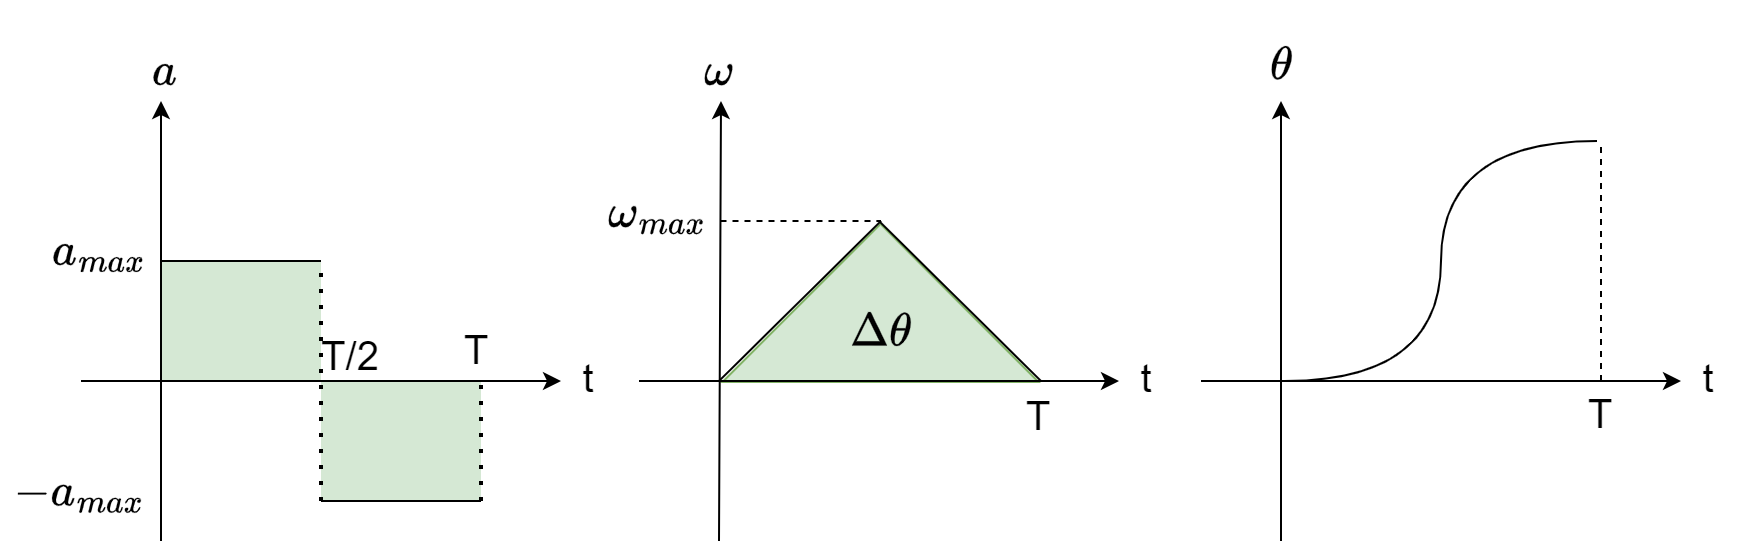**그림 1**

**2.1** Bang-off-bang 프로파일로부터 제약 조건 1번을 만족할 수 있는 리액션 휠 성능과, 제약 조건 2번을 만족할 수 있는 리액션 휠 성능 각각을 도출하시오.

% Parameter
I                   = 0.1;              % [kg m^2]
dtheta              = [10 ; 20].*D2R;   % [rad]
T                   = [15 ; 25];        % [sec]

% ==================== DIY ====================
% Case 1: dtheta=10deg, T=15

% Case 2: dtheta=20deg, T=25

% ==================== DIY ====================

**2.2** 조건 1(15초에 10도)과 조건 2(25초에 20도) 중 더 큰 리액션 휠 모멘텀을 요구하는 경우는?

**2.3** 조건 1(15초에 10도)과 조건 2(25초에 20도) 중 더 큰 리액션 휠 토크를 요구하는 경우는?

**2.4** 문제 2.2와 2.3의 결과로부터 두 제약 조건을 모두 만족시킬 수 있는 리액션휠의 성능을 선정하고, 이문제로부터 얻을 수 있는 사실을 제시하라(힌트: 주어진 시간과 기동각에 따라 요구되는 토크와 모멘텀 비교)

**2.5** 문제 2.4에서 결정한 휠의 성능을 그대로 이용하여 자세 프로파일을 생성해보자.

아래 그림은 Bang-off-bang 제어기에 의해 생성되는 자세 프로파일을 나타낸 것이다. Bang-off-bang 제어기는 요구되는 기동각이 큰 경우에 적용할 수 있는 제어 기법이다.

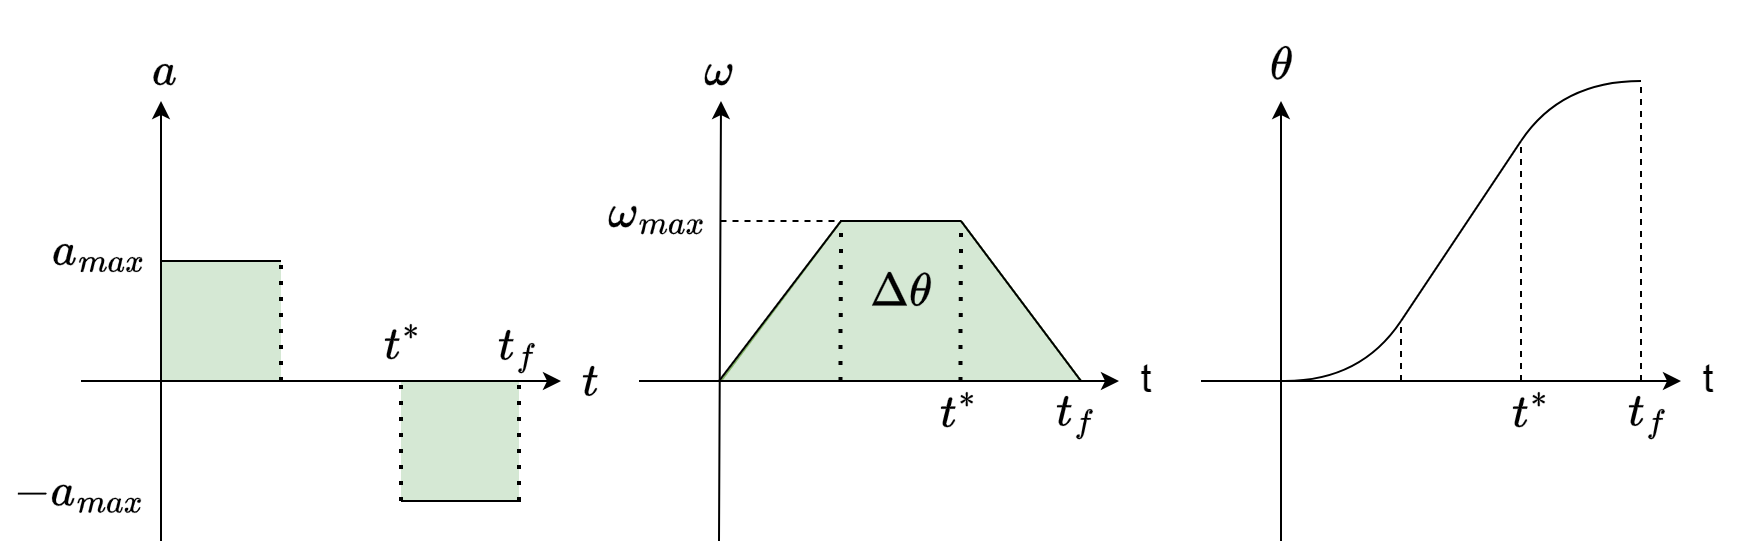**그림 2**

Bang-bang 제어기와 Bang-off-bang 제어기 중 어떤 방식을 사용할지 판단하는 기준은 다음과 같다. 먼저 요구 기동각을 $\Delta \theta$라고 하자. Bang-bang 제어기를 적용했을 때 도달 가능한 최대 기동각은 그림 1의 프로파일로 부터 다음과 같이 유도된다. 


$$\Delta \theta_{\mathrm{crit}} =\frac{\omega_{\max }^2 }{a_{\max } }$$


따라서 요구되는 기동각($\Delta \theta$)이 $\Delta \theta_{\mathrm{crit}}$보다 크다면 Bang-off-bang 제어기를, 작으면 Bang-bang 제어기를 고려할 수 있다. 

이제 이를 코드로 구현해보자. 아래 코드에서는 문제 2.4에서 구한 $h_{\mathrm{RW},\max } ,\tau_{\mathrm{RW},\max }$를 입력값으로 사용한다. 또한 **요구 기동각이 (1) 5도, (2) 50도** 인 경우에 대해, Bang-bang 또는 Bang-off-bang 제어기를 적용하여 각각의 자세 프로파일이 생성되도록 함수를 구현한다.

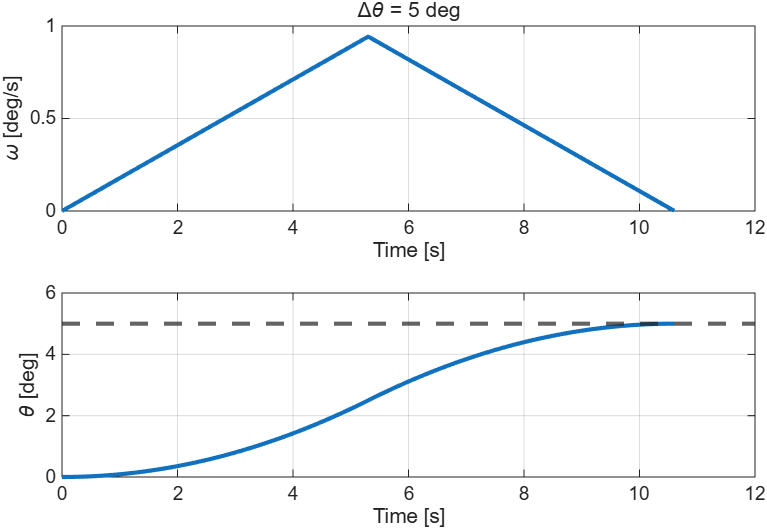

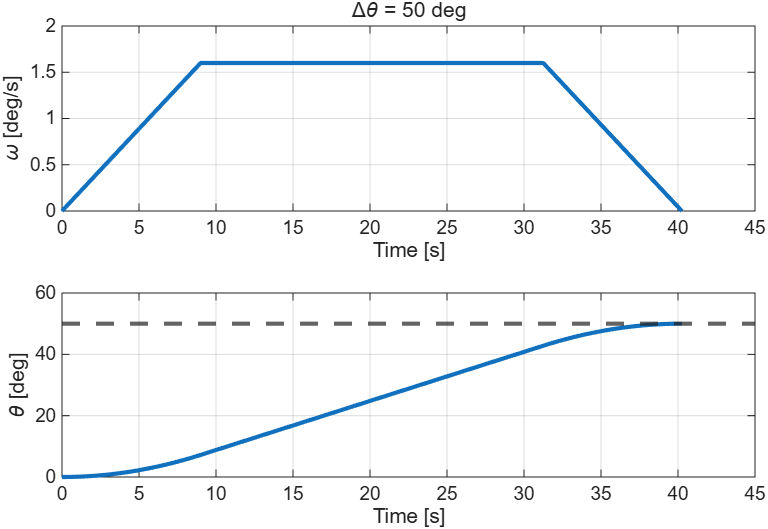

% Parameter @ Problem 2.1 ~ 2.4
I                   = 0.1;              % [kg m^2]

% ==================== DIY ====================
h_RW_max            = [];               % [N m s] reaction wheel momentum capacity
tau_RW_max          = [];               % [N m] reaction wheel torque capacity
% ==================== DIY ====================

% Maneuver Requirements
dt                  = 0.01;
dtheta              = [5 ; 50].*D2R;    % [rad]

if isempty(h_RW_max) && isempty(tau_RW_max)
    % Do nothing
else
    for k = 1 : length(dtheta)
        w_max = h_RW_max / I;
        a_max = tau_RW_max / I;

        dtheta_temp = dtheta(k);

        [t, omega, theta, acc] = make_att_profile(dtheta_temp, w_max, a_max, dt);

        % Plot
        figure;
        subplot(2,1,1) % t-w
        plot(t, omega.*R2D , 'LineWidth',2)
        grid on
        xlabel('Time [s]')
        ylabel('\omega [deg/s]')
        title(sprintf('\\Delta\\theta = %.0f deg', dtheta_temp*R2D))
        subplot(2,1,2) % t-theta
        plot(t, theta.*R2D , 'LineWidth',2)
        hold on
        yline(dtheta_temp*R2D,'LineWidth',2,'LineStyle','--')
        grid on
        xlabel('Time [s]')
        ylabel('\theta [deg]')      

    end
end

% ==================== DIY ====================
function [t, omega, theta, acc] = make_att_profile(dtheta, w_max, alpha_max, dt)

    % Critical angle required to reach maximum angular velocity
    dtheta_crit = w_max^2 / alpha_max;
    
    if dtheta >= dtheta_crit
        %% Bang-off-bang profile
    
    else
        %% Bang-bang profile
    
    end
end
% ==================== DIY ====================

**2.6** 이제 Agility table을 만들어보자. 기동각 $\Delta \theta =\left\lbrack \begin{array}{cccc}
5^{\circ }  & {10}^{\circ }  & \cdots  & {50}^{\circ } 
\end{array}\right\rbrack$ 일때, 각각에 대해 몇초 만에 도달할 수 있는지 아래와 같은 그래프를 만들어보자.

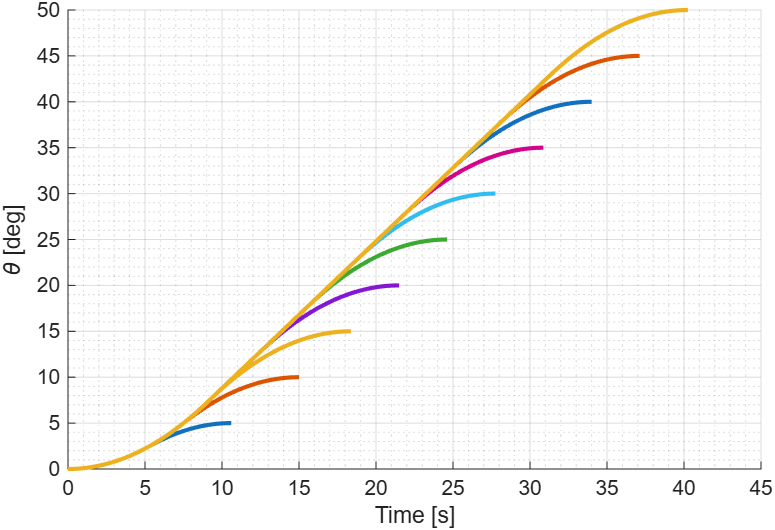

dtheta              = (5:5:50).*D2R;    % [rad]
data_len            = length(dtheta);

if isempty(h_RW_max) && isempty(tau_RW_max)
    % Do nothing
else
    % ==================== DIY ====================
  
    % ==================== DIY ====================
end